**Numerical Methods Midterm Exam 2022 - Solutions**

a. Find and display all **real roots** of the following polynomial to 8 decimal places accuracy.


$$\(p\left(x\right)=2x-5x^2-x^3-2x^7\)$$


% Enter solution here
s = roots([-2, 0, 0, 0, -1, -5, 2, 0])

s =    0.0000 + 0.0000i
  -1.2206 + 0.0000i
  -0.4909 + 1.1348i
  -0.4909 - 1.1348i
   0.9155 + 0.7779i
   0.9155 - 0.7779i
   0.3714 + 0.0000i


s = s(s==real(s))

s =          0
   -1.2206
    0.3714


b. Plot the polynomial over an appropriate domain and mark on the real roots with large red circles.

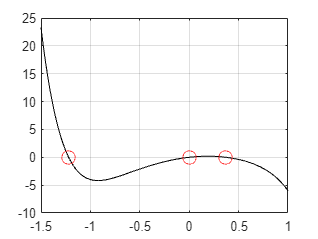

% Enter solution here
p = @(x) 2 .* x - 5 .* x.^2 - x.^3 - 2 .* x.^7;
q = linspace(-1.5,1,100);
plot(q, p(q), 'color', 'black')
hold on
plot(s, p(s), 'o', 'MarkerEdgeColor','r', 'MarkerSize', 10);
hold off
grid on

c. Find the locations of any local extrema of $p(x)$ and plot them with large green diamonds.

% Enter solution here
pp = [-2, 0, 0, 0, -1, -5, 2, 0];
dp = polyder(pp);
localEx = roots(dp);
localEx = localEx(localEx==real(localEx))

localEx =    -0.9233
    0.1892


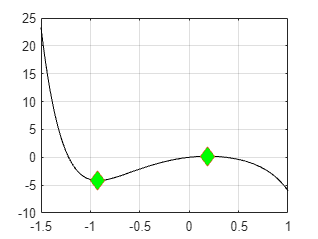


% graph
plot(q, p(q), 'color', 'black')
hold on
plot(localEx, p(localEx), 'd', 'MarkerFaceColor','g', 'MarkerSize', 10);
hold off
grid on

d. Find the locations of any points of inflections and plot them with large purple stars.

% Enter solution here
ddp = polyder(dp)

ddp =    -84     0     0     0    -6   -10


ifp = roots(ddp)

ifp =    0.5454 + 0.4291i
   0.5454 - 0.4291i
  -0.2465 + 0.5939i
  -0.2465 - 0.5939i
  -0.5978 + 0.0000i


ifp = ifp(ifp == real(ifp))

ifp = -0.5978

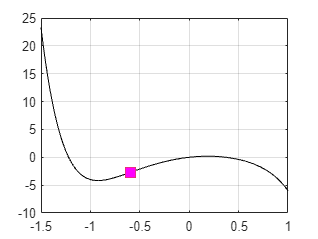


% graph
plot(q, p(q), 'color', 'black')
hold on
plot(ifp, p(ifp), 's', 'MarkerFaceColor','magenta', 'MarkerSize', 10);
hold off
grid on

2.  The speed v of a Saturn V rocket in vertical flight near the surface of earth can be approximated by:

where,

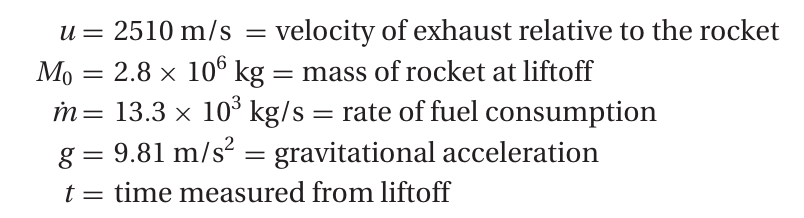

Determine the time when the rocket reaches the speed of sound (335 m/s).

% Enter solution here
time = 0;
speed = 0;
speedSound = 335;
t = 1;
while speed < speedSound
    speed = 2510 * log((2.8 * 10^6)/(2.8 * 10^6 - 13.3 * 10^3 * t));
    if speed < speedSound
        t = t + 0.000001;
    end
end
t

t = 26.3038

speed

speed = 335.0000

3. Find all real solutions to the following system of equations on the domain $-\pi/2 \leq x\leq \pi/2, \,\,\,\, -5 \leq y\leq 5$ to 7 decimal places then create a plot which displays the solution.


$$\tan(2x - 1)=1 + \cos(y) \\
\cos(x)=2\sin^2(y)$$


% Enter solution here
xVal = [];
for x = (-pi/2):(pi/2)
    a = tan((2*x)-1);
    b = 1 + sqrt(1-(1/2)*cos(x));
    if a == b
        x
        xVal(end + 1) = x;
    end
end
xVal


xVal =

     []



4. Three tensile tests were carried out on an aluminium bar. In each test the strain was measured at the same values of stress.

The results were:

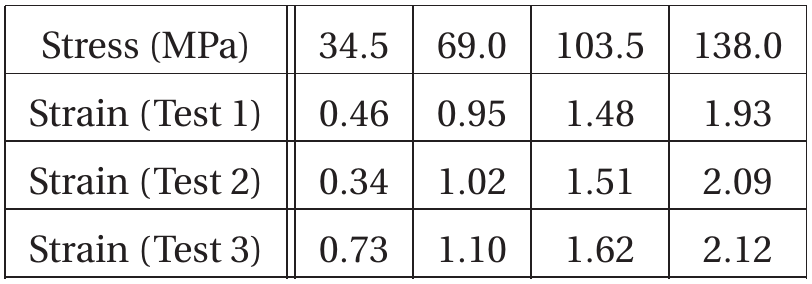

where the units of strain are mm/m ("millimetres per metre"). 

Plot the data then use linear regression to estimate the modulus of elasticity of the bar (modulus of elasticity = stress/strain). Plot the regression line on the same figure as the data.

% Enter solution here


5. The following data is to be fit to a power equation of the form,

$w = Ax^By^Cz^D$,

where A, B, C and D are constants. 

Use linearisation and regression to estimate the values of A. B. C and D then use the fitted power equation to estimate the value of w at the point $(x,y,z) = (3.5, 2.3, 7.1)$.

Data:


$$\matrix{
x & y & z & w \cr
4 & 6 & 8 & 34.68 \cr
1 & 6 & 12 & 9.47 \cr
2 & 10 & 12 & 25.61 \cr
1 & 10 & 6 & 5.97 \cr
1 & 4 & 6 & 4.46 \cr
5 & 7 & 10 & 58.22 \cr
4 & 6 & 15 & 61.07 \cr
2 & 9 & 8 & 17.19 \cr
5 & 9 & 11 & 68.75 \cr
1 & 10 & 7 & 6.86 \cr
}$$


% Enter solution here


6. Consider the following multivariable function:


$$\(f\left(x,y\right)=\frac{10-y}{x-3}\)$$


We wish to evaluate $\(f\left(\frac{1,000,000}{333,333},\frac{5}{7}\right)\)$ in Matlab.

a. What is the true relative error when rounding the $x$ and $y$ values to 6 decimal places in the calculation?

% Enter solution here


b. What is the true absolute error when using double precision in the calculation?

% Enter solution here


c. To calculate the relative error in part (a) you had to divide a relatively small number by a relatively large number. Can you trust that value or not? Explain/demonstrate why the relative error you calculated can either be trusted or not.

% Enter solution here


 --- FUNCTIONS ---

A space to place your functions so that after running the code blocks below you can then use them in the scripts above.